# SHAppE Getting Started Guide

## Opening SHAppE

After installing SHAppE an App shortcut will be added to the APPS tab in MATLAB.

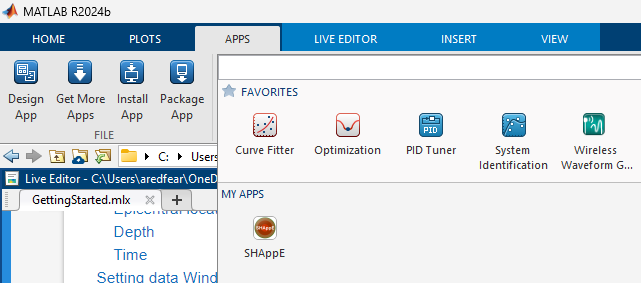

To open SHAppE click this shortcut or use the button below

 
SHAppE_launcher

## Data

### **Seismic Data**

SHAppE requires a time series seismic dataset containing the vairables listed below:

- Time (One column with a common datetime format)

- Longitude

- Latitude

- Magnitude

- Depth

The data must be an excel document or csv file containing a column for each required variable.

An example dataset `Vietnam_Seismic_Data.xlsx` is provided with SHAppE.

### **Production Data**

Additionally you can include production data for use when selecting time windows and in the final visualisation. This is provided as an additional excel or csv file containing contain a time variable. All other variables will be imported as production data. Production data can be any time-correlated parameter such as fluid injection or extraction rate/volume, reservoir water level, ocean water level fluctuation due to tides etc.

An example dataset `Vietnam_Production_Data.xlsx` is provided with SHAppE.

Use the button below to add the example data files to your working directory and open in excel.

### Importing 

When you first open SHAppE you will start at the Import tab. Use the browse buttons to pick your seismic and production data files. If you are not including production data leave blank.

Next specify the column number of each required variable in your file(s).

Then press Import to import the data. If successful you will see a preview of the imported data. This shows how the data is known to SHAppE, make sure it is as you expect.

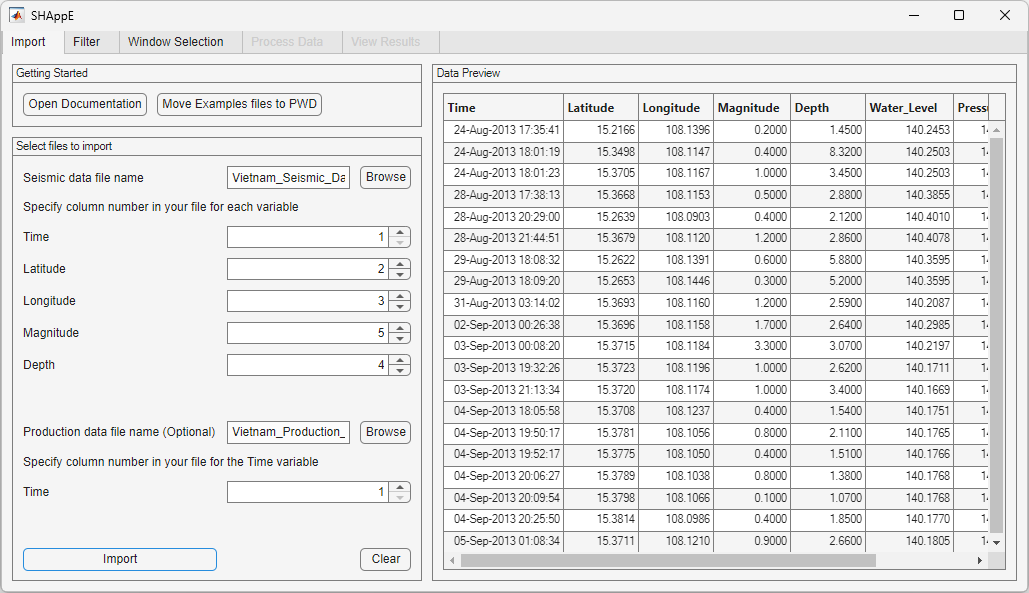

When combining Seismic and Production data the Seismic data timebase is used. Any times outside this range in the Production data are removed and the data in linearly interpolated to match that of Seismic data if required.

## Filtering Data

You can filter your data based on a magnitude, epicentral location, depth and time data.

Currently applied filtered are shown in the table on the right-hand side of the "Filter" tab.

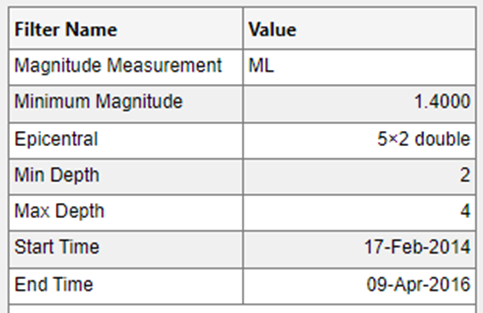

### Magnitude

Select a chosen magnitude variable and minimum magnitude value. Click ‘Apply Filter’ to update the data.

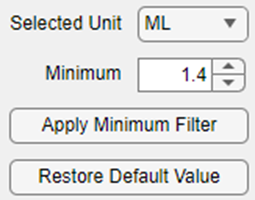

To reset this filter, click ‘Restore Default Value’

### Epicentral location

To filter data points by epicentral location data click ‘Draw New ROI’ button and then draw a polygon area onto the map by clicking to create vertices.

Once an enclosed area is complete click ‘Apply Filter’ to update the data.

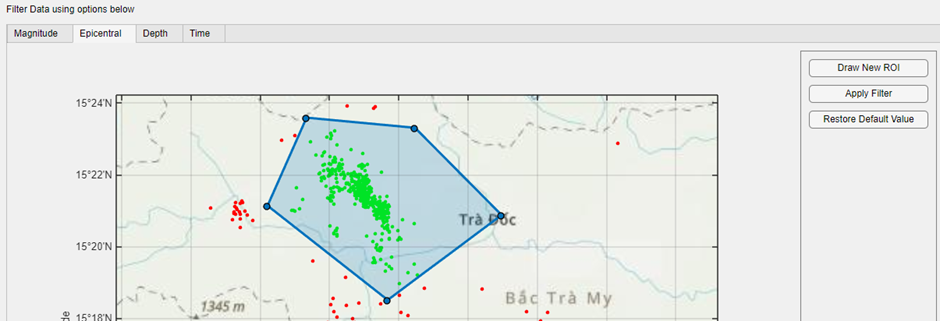

To reset this filter, click ‘Restore Default Value’.

### Depth

To filter data points by depth, select a minimum and maximum depth value and click ‘Apply Filter’

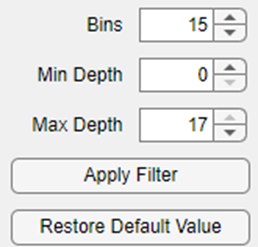*should these all be full screenshots rather than cropped*

To reset this filter, click ‘Restore Default Value.’

### Time

To filter data by time, select the start and end dates either interactively by cliking twice on the chart, or by using the date pickers.

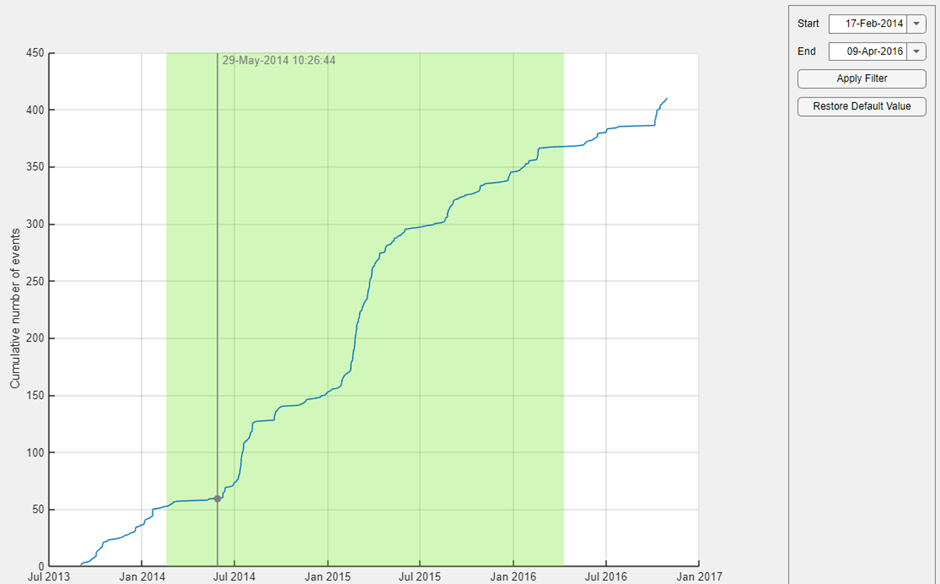

Once selected click ‘Apply Filter’ to update the data.

To reset this filter, click ‘Restore Default Value.’

## Setting data Windows

There are four methods for setting the processing windows. The data within each time window will be processed according to the method you select in the "Processing Data" tab.

You can select time windows by:

- **Time**: Choosing a window size and step size in days

- **Events**: Choosing a window size and step size in number of events

- **File**: Uploading an Excel file which lists time windows using date and time values. First column is start time, second column is end time in any [datetime format](https://www.mathworks.com/help/releases/R2024b/matlab/ref/datetime.html?searchPort=54532) (see the example file '*Example_Windows.xlsx'*).

- **Graphical**: Select start and end point for each window graphically by clucking on a chart plotting a chosen variable against time.

Once you have selected window by one of the methods above click ‘Set Windows’ and you will see the selected windows displayed in the table on the right hand side.

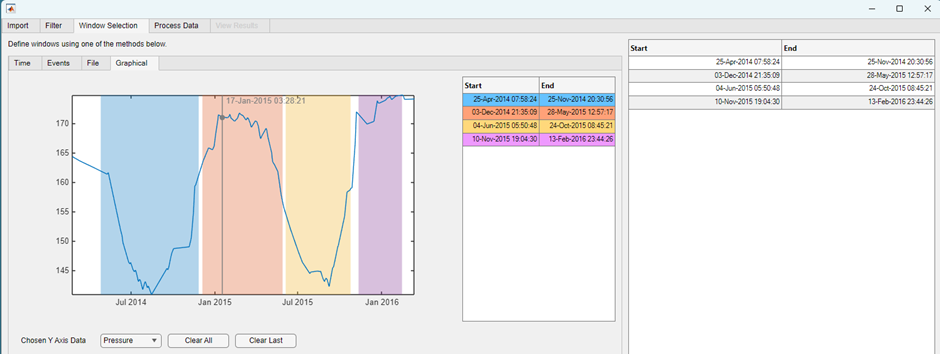

You can change your selection or move to the "Process Data" tab.

## Processing data

You can process data using either the Gutenberg-Richter law (GR) or a non-parametric Kernel Density estimation (NP). 

In both cases truncated or not truncated distribution options are available. Truncated distributions consider a Maximum Magnitude value.

Values for Maximum Magnitude, target period length and confidence interval calculation can also be set in the "Process Data" tab.

For more information please refer to [Leptokaropoulos and Lasocki, SRL, 2020](https://pubs.geoscienceworld.org/ssa/srl/article-abstract/91/3/1867/583455/SHAPE-A-MATLAB-Software-Package-for-Time-Dependent?redirectedFrom=fulltext).

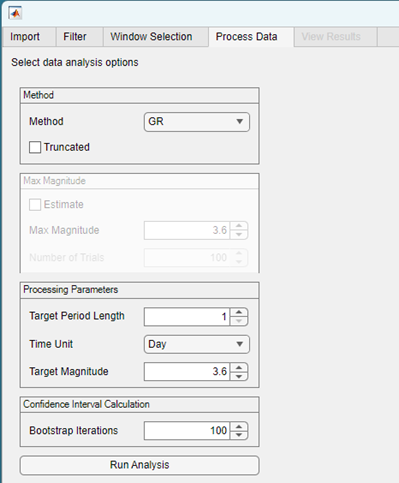

These setting determine which method is used and with what input parameters.

Click ‘Run Analysis’ to process and move to the View Results tab.

## Viewing and Exporting results

Results for mean return period, exceedance probability and activity rate for each time window are shown as charts or as a table in the "View Results" tab.

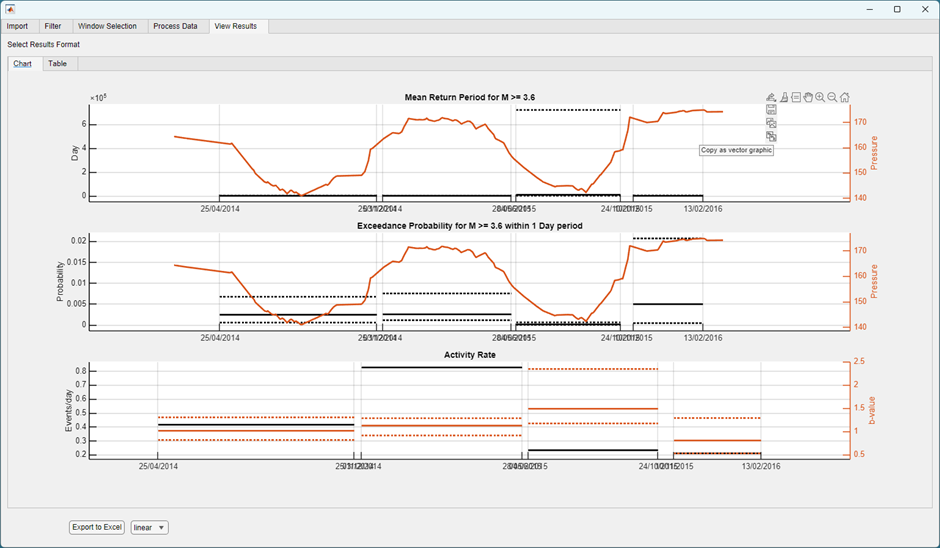

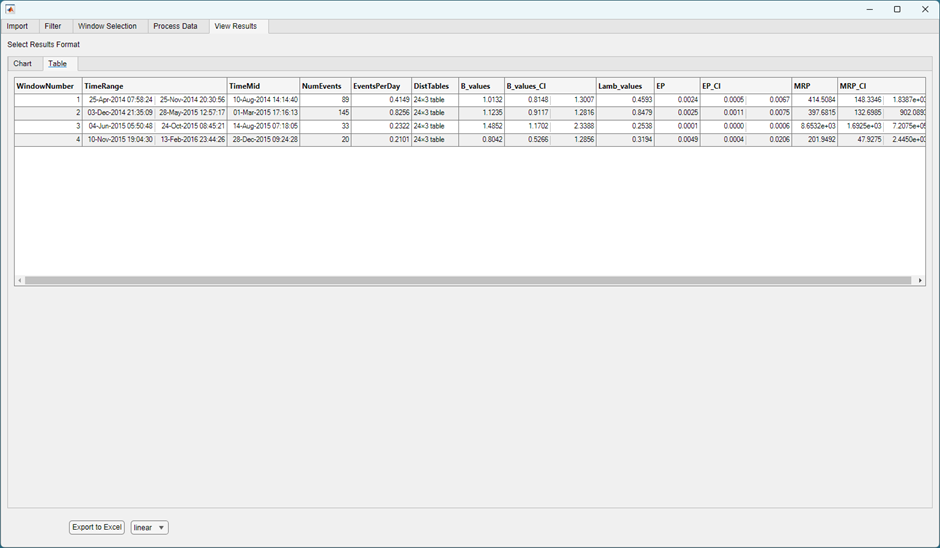

Export the visualisation using the built in menu buttons shown above, as either a MATLAB figure, image or vector graphic.

## Exporting workflow

From the "View Results" tab you can export results along with details of you workflow choices to an excel document by clicking "Export to Excel".

The resulting document contains a sheet for each tab to record the data source, filters selected, time windows chosen, processing method and parameters selected, along with the results table.

### Importance of Record Keeping

Maintaining a detailed record of all results and parameters selected is crucial for several reasons:

- Reproducibility: Accurate documentation ensures that experiments can be replicated under the same conditions, which is essential for verifying results and conducting further research.

- Convenience: Having a comprehensive record of different input/output configurations allows for easy reference and comparison, saving time and effort in future analyses.

- Transparency: Clear records enhance the transparency of your workflow, making it easier to understand and communicate the steps taken during the experiment.

## References

Leptokaropoulos and Lasocki (2020), SHAPE: A MATLAB Software Package for Time‐Dependent Seismic Hazard Analysis, Seismol. Res. Lett., [https://doi.org/10.1785/0220190319](https://doi.org/10.1785/0220190319). 

## Need Help?

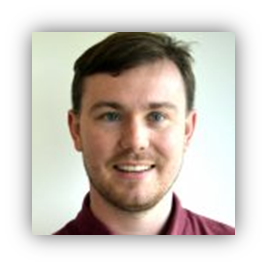Andrew Redfearn: [aredfear@mathworks.com](mailto:aredfear@mathworks.com)

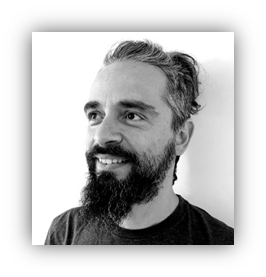 Kostas Leptokaropoulos: [kleptoka@mathworks.com](mailto:kleptoka@mathworks.com)